# ***1) Considere um sinal x[n] disponível através dos arquivos ‘dados.txt’ ou ‘dados.mat’. Este sinal  foi amostrado com uma frequência de 18.000 Hz. Utilizando uma linguagem  de programação adequada:***

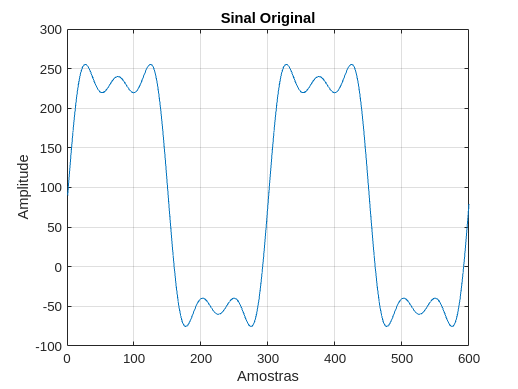

clc;
clear;

dados = importdata('dados.txt');

% Considerando que o sinal foi amostrado corretamente a freq maxima
% que pode estar contida no sinal sera metade de Fs -> pelo teorema de nyquist
Fs = 18000;
Fmax = Fs/2; 

figure;
plot(dados);
title('Sinal Original');
xlabel('Amostras');
ylabel('Amplitude');
grid on;

**a. Utilize a equação de análise da Série Discreta de Fourier e obtenha os valores dos coeficientes X~[*****n*****]**

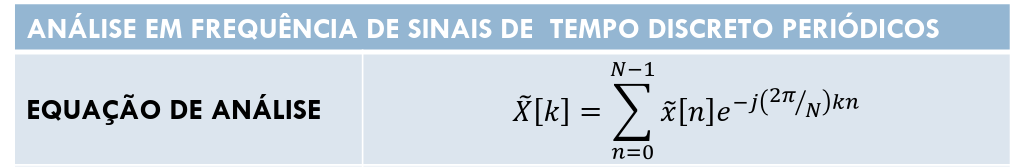

function X = eq_analise(sinal, k)
    X = 0;
    N = length(sinal);
    for n = 0:N-1
        X = X + (sinal(n+1) * exp(-1i * (2*pi/N) * k * n));
    end
end

K = [];
N = length(dados);
coeficientes = zeros(1, N);
for k = 0:N-1
    K = [K, k];
    coeficientes(k+1) = eq_analise(dados, k);
end

fase = angle(coeficientes);
magnitude = abs(coeficientes);  
frequencias = (0:N-1)*(Fs/N);

**b. Apresente o gráfico de barras dos valores de ∣*****X*****~[*****n*****]∣ e ∠*****X*****~[*****n*****] em função de *****k*****. Quais as componentes múltiplas da frequência fundamental existentes?**

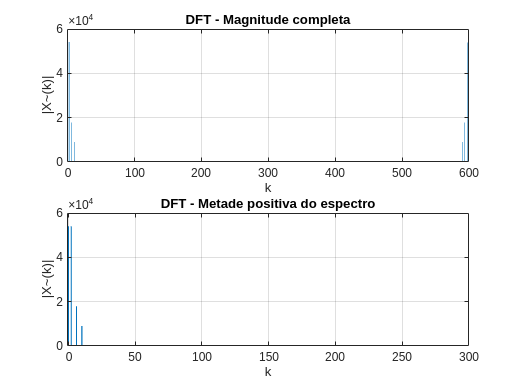

% Gráficos de Magnitude
figure;
subplot(2,1,1);
bar(K, magnitude);
title('DFT - Magnitude completa');
xlabel('k');
ylabel('|X~(k)|');
grid on;
subplot(2,1,2);
bar(K(1:N/2), magnitude(1:N/2));
title('DFT - Metade positiva do espectro');
xlabel('k');
ylabel('|X~(k)|');
grid on;

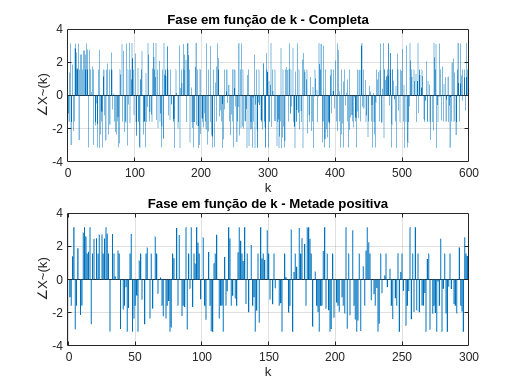


% Gráficos de Fase
figure;
subplot(2,1,1);
bar(K, fase);
title('Fase em função de k - Completa');
xlabel('k');
ylabel('∠X~(k)');
grid on;
subplot(2,1,2);
bar(K(1:N/2), fase(1:N/2));
title('Fase em função de k - Metade positiva');
xlabel('k');
ylabel('∠X~(k)');
grid on;


fprintf("A freq fundamental sera k=%d com magnitude=%d", K(3), magnitude(3))

A freq fundamental sera k=2 com magnitude=5.400000e+04

disp("E as frequencias divisiveis por ela são:")

E as frequencias divisiveis por ela são:


for k = 4:length(K(1:N/2))
    if mod(K(k), K(3)) == 0 && magnitude(k) > 0.1
        disp(K(k))
    end    
end

     6

    10



**c. Apresente o gráfico de barras dos valores de ∣∣*****X*****~[*****n*****]∣∣ e ∠*****X*****~[*****n*****] em função de *****f*****(*****Hz*****). Que frequências compõem o sinal com base na análise de Fourier? Quais suas amplitudes?**

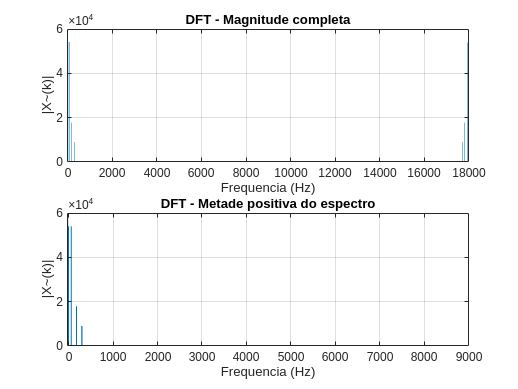

% Gráficos de Magnitude
figure;
subplot(2,1,1);
bar(frequencias, magnitude);
title('DFT - Magnitude completa');
xlabel('Frequencia (Hz)');
ylabel('|X~(k)|');
grid on;
subplot(2,1,2);
bar(frequencias(1:N/2), magnitude(1:N/2));
title('DFT - Metade positiva do espectro');
xlabel('Frequencia (Hz)');
ylabel('|X~(k)|');
grid on;

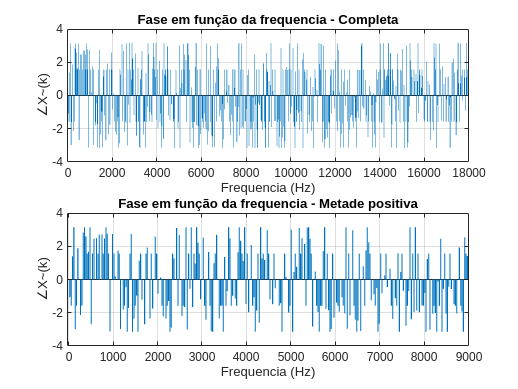


% Gráficos de Fase
figure;
subplot(2,1,1);
bar(frequencias, fase);
title('Fase em função da frequencia - Completa');
xlabel('Frequencia (Hz)');
ylabel('∠X~(k)');
grid on;
subplot(2,1,2);
bar(frequencias(1:N/2), fase(1:N/2));
title('Fase em função da frequencia - Metade positiva');
xlabel('Frequencia (Hz)');
ylabel('∠X~(k)');
grid on;


fprintf("A freq fundamental sera %d com magnitude=%d", frequencias(3), magnitude(3)/N)

A freq fundamental sera 60 com magnitude=9.000000e+01

disp("E as frequencias divisiveis por ela são:")

E as frequencias divisiveis por ela são:


for k = 1:length(frequencias(1:N/2))
    if magnitude(k) > 0.1
        fprintf("%d: %d\n", frequencias(k), magnitude(k)/N); 
    end
end

0: 9.000000e+01
60: 9.000000e+01
180: 3.000000e+01
300: 1.500000e+01


**d. Considerando que o sinal é do tipo *****x*****[*****n*****]=*****Vcc*****+*****A*****1*****sin*****(2*****πf*****1/*****Tn*****)+*****A*****2*****sin*****(2*****πf*****2/*****Tn*****)+*****A*****3*****sin*****(2*****πf*****3/*****Tn*****), com base na análise de Fourier, defina os valores de *****Vcc*****, *****A*****1, *****A*****2, *****A*****3, *****f*****1, *****f*****2, *****f*****3.**

Vcc = `9.000000e+01`

*A*1 = `9.000000e+01 / `*A2* = `9.000000e+01 / `*A3* = `3.000000e+01`

*f*1 = 60` / `*f*2 = `180 / `*f*3 = 300

**e. Com base em *****X*****~[*****n*****] e na equação de síntese da Série Discreta de Fourier, reconstrua o sinal *****x*****[*****n*****] apresentando seu gráfico.**

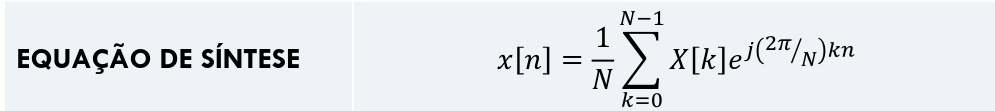

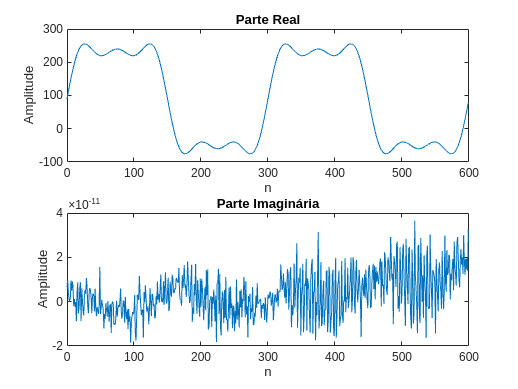

function X = eq_sintese(coeficientes, n, N)
    X = 0;
    for k = 0:N-1
        X = X + (coeficientes(k+1) * exp(1i * (2*pi/N) * k * n));
    end
    X = X/N;
end

sample = [];
sinal = zeros(1, N);
for n = 0:N-1
    sample = [sample, n];
    sinal(n+1) = eq_sintese(coeficientes, n, N);
end

figure;
subplot(2,1,1);
plot(sample, real(sinal));
title('Parte Real');
xlabel('n');
ylabel('Amplitude');

subplot(2,1,2);
plot(sample, imag(sinal));
title('Parte Imaginária');
xlabel('n');
ylabel('Amplitude');

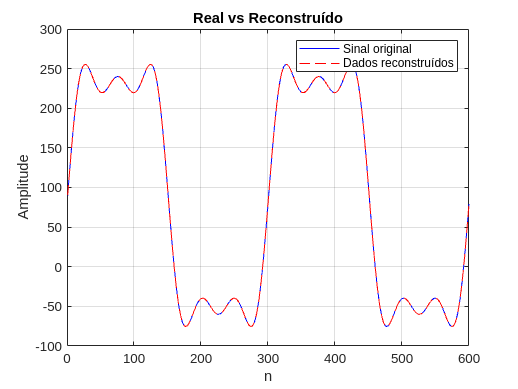


figure;
plot(real(sinal), 'b', 'DisplayName', 'Sinal original');
hold on;
plot(dados, 'r--', 'DisplayName', 'Dados reconstruídos');
title('Real vs Reconstruído');
xlabel('n');
ylabel('Amplitude');
legend('show');
grid on; 

**f. Utilizando o comando fft de uma implementação computacional (Matlab,  Python, etc) refaça os itens a, b, c, d. Compare os resultados. **

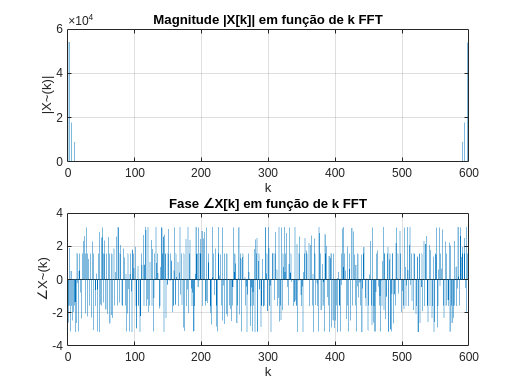

coef_fft = fft(dados); % Calcula a FFT (implementação rápida da DFT)
mag_fft = abs(coef_fft); % Magnitude
phase_fft = angle(coef_fft); % Fase (ângulo)

figure;
subplot(2,1,1);
bar(K, mag_fft);
title('Magnitude |X[k]| em função de k FFT');
xlabel('k');
ylabel('|X~(k)|');
grid on;

subplot(2,1,2);
bar(K, phase_fft);
title('Fase ∠X[k] em função de k FFT');
xlabel('k');
ylabel('∠X~(k)');
grid on;


fprintf("FFT: A freq fundamental sera %d com magnitude=%d", frequencias(3), mag_fft(3)/N)

FFT: A freq fundamental sera 60 com magnitude=9.000000e+01

disp("E as frequencias divisiveis por ela são:")

E as frequencias divisiveis por ela são:


for k = 1:length(frequencias(1:N/2))
    if mag_fft(k) > 0.1
        fprintf("%d: %d\n", frequencias(k), mag_fft(k)/N); 
    end
end

0: 9.000000e+01
60: 9.000000e+01
180: 3.000000e+01
300: 1.500000e+01


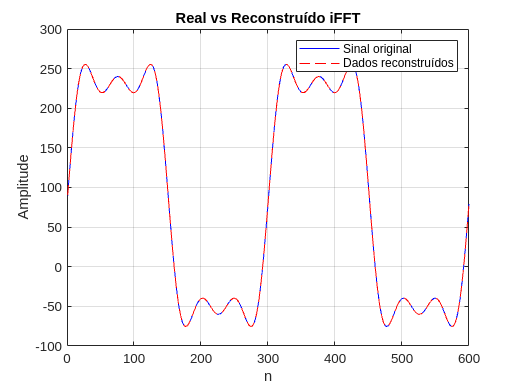


sinal_fft = ifft(coef_fft);
figure;
plot(real(sinal_fft), 'b', 'DisplayName', 'Sinal original');
hold on;
plot(dados, 'r--', 'DisplayName', 'Dados reconstruídos');
title('Real vs Reconstruído iFFT');
xlabel('n');
ylabel('Amplitude');
legend('show');
grid on; 

*FFT: *

*x*[*n*]=*Vcc*+*A*1*sin*(2*πf*1/*Tn*)+*A*2*sin*(2*πf*2/*Tn*)+*A*3*sin*(2*πf*3/*Tn*)

Vcc = `9.000000e+01`

*A*1 = `9.000000e+01 / `*A2* = `9.000000e+01 / `*A3* = `3.000000e+01`

*f*1 = 60` / `*f*2 = `180 / `*f*3 = 300

Comparando as coeficientes e fases:

disp(fase);

         0   -1.0670   -1.5708    1.4064    3.1416   -2.9832   -1.5708    1.8788    0.0000   -2.1335   -1.5708    2.8285    3.1416    2.5904    1.5708    1.6760    3.1416   -2.6933    1.5708    2.4580    0.0000    2.4898    1.5708    2.7127    0.0000    2.7120    1.5708    2.4606    3.1416    2.7572    1.5708   -3.1239    0.0000    2.7369    1.5708    0.1999   -0.0000    1.7487    1.5708   -2.9709    0.0000   -1.8067   -1.5708   -0.4636   -3.1416   -1.7064    1.5708    2.7369   -3.1416   -2.3635   -1.5708   -0.9651   -3.1416    1.1409    1.5708   -1.2219    0.0000   -2.6826    1.5708    1.9207    0.0000   -2.3478    1.5708   -1.7400    0.0000    2.5892    1.5708   -0.8511   -0.0000    0.1160   -1.5708   -2.2066    0.0000   -2.3482   -1.5708   -1.2870   -3.1416   -2.8835    1.5708    1.2745   -0.0000    3.0925   -1.5708    2.6800    0.0000   -2.1975   -1.5708   -1.6528    3.1416   -3.0001    1.5708   -0.5504    3.1416   -1.6494    1.5708    0.9705    3.1416    2.2283    1.5708   -1.1813

disp(phase_fft);

         0   -2.5687   -1.5708    1.9141   -3.1416    0.5083   -1.5708   -2.4803   -0.0000   -1.9507   -1.5708   -1.3517   -3.1416   -2.6143    1.5708   -0.1918   -3.1416    0.5298    1.5708   -0.7704    0.0000   -2.3303    1.5708    2.3067    0.0000    2.6217    1.5708   -2.0408    3.1416   -2.2311    1.5708    1.2332    0.0000   -1.5613    1.5708   -2.3027   -0.0000    2.3011    1.5708   -3.0151    0.0000   -0.6460   -1.5708    0.3749   -3.1416   -0.6029    1.5708    2.8635   -3.1416   -1.5127   -1.5708    2.5480    3.1416   -1.3963    1.5708    2.3293   -0.0000   -1.7838    1.5708   -2.0791   -0.0000    2.5658    1.5708   -2.6265    0.0000   -2.1323    1.5708   -2.3092    0.0000    1.8736   -1.5708    0.4444   -0.0000    2.6084   -1.5708    3.1416    3.1416   -1.3842    1.5708    2.0726    0.0000   -1.5620   -1.5708    1.8474   -0.0000    1.3044   -1.5708    0.3130   -3.1416   -2.0586    1.5708   -0.5738   -3.1416    0.3369    1.5708   -0.7388   -3.1416    1.7845    1.5708    0.6904

%angulos da fase não estão batendo

disp(coeficientes);

   1.0e+04 *

   5.4000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 5.4000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 1.8000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.9000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.000

disp(coef_fft);

   1.0e+04 *

   5.4000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 5.4000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 1.8000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.9000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.000

%coeficientes estão iguais, mas não estou entendo o por que a fase esta
%dando difença

Comparando minha implementação da DFT com a FFT implementada pelo matlab posso dizer que, em relação aos resultados, os algoritmos apenas se divergiram na fase calculada. Talvez seja por algum arredondamento, ou apenas um erro cometido de minha parte no cálculo.